The goal of this assignment is to recreate the forest and the trees simulation.

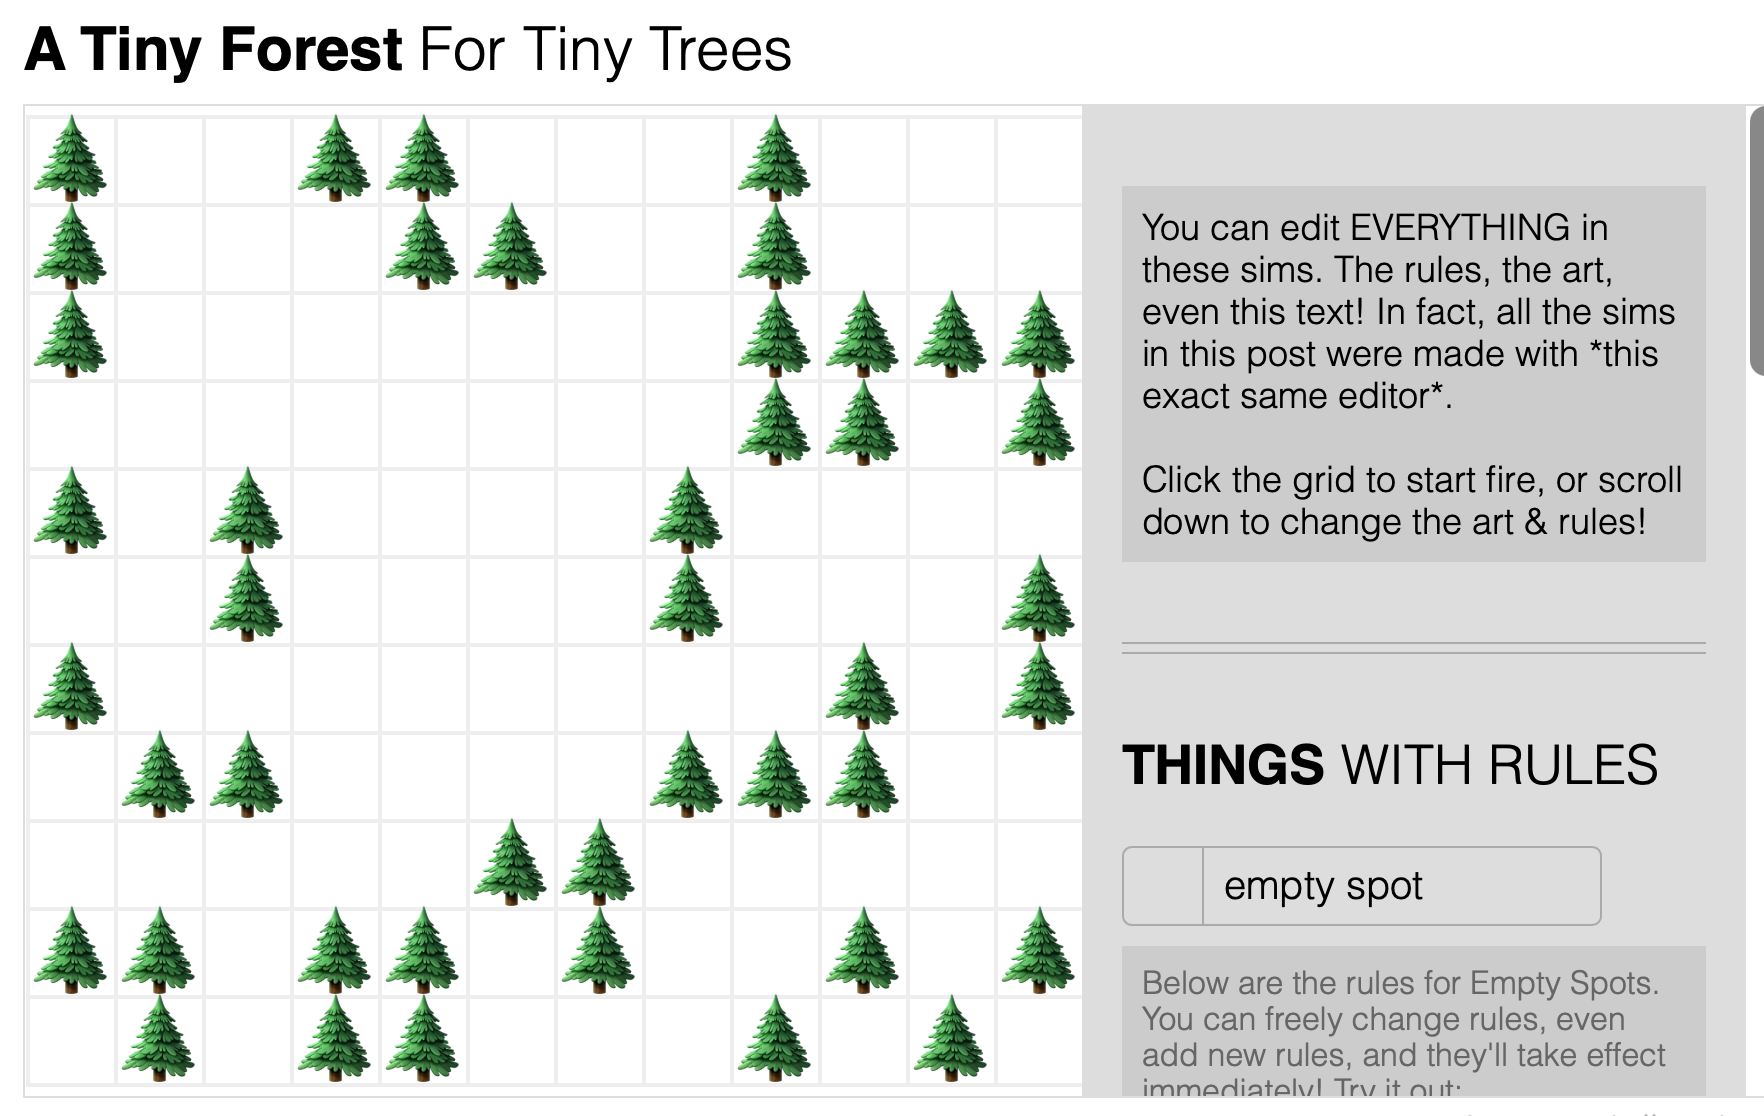

Similar to past simulations, you will be looking at a variable at a moment in time, applying some rules or equations to that variable, and then determining the variable at the next moment in time.

But there are several differences from past simulations:

- The forest data is in two dimensions 

- Each cell of the forest data has three different possible states: empty, tree, and fire

**Task 1:**

Start by initializing your variables.

- forestSizeX, forestSizeY: these will specify the overall size of your forest

- forest(): this will be the 2D matrix that contains the information about your forest. You should initialize this with the zeros function. 

- forestNext(): this will be the forest at the next point in time. Initialize this with the zeros function just like the forest matrix

- Each cell of forest() and forestNext() can contain three different values. Setup these variables that you will assign to these cells: empty=0; tree=1; fire=2;

- treeGrowthRate: this is the chance that a blank square turns into a tree. As a starting point use 1% or 0.01

- treeDeathRate: this is the chance that a tree will natually die from a means other than fire (this was not part of the original simulaiton). As a starting point, use 0.1% or 0.001

- fireSparkRate: this is the chance that a tree will catch on fire from a lightning strike or human accident. As a starting point, use 0.1% or 0.001.

- simulationTimeSteps: this is how many time steps you will have in your simulation. A good starting point is 1000.

clc;clear;%Clean the workspace
close all; %Close all the existing figures

%initialize variables as described above
forestSizeX = 20;
forestSizeY = 20;
forest = zeros(forestSizeX,forestSizeY);
forestNext = zeros(forestSizeX,forestSizeY);
empty = 0;
tree = 1;
fire = 2;
treeGrowthRate = 0.01;
treeDeathRate = 0.001;
fireSparkRate = 0.001;
simulationTimeSteps = 1000;



**Task 2:**

Display the forest as an image graph just to make sure that everything looks ok. Use the imagesc command. Set clims (color limits) to [0 2], which is the range of possible data values in your forest. The resulting figure should be a blank blue background grid with size forestSizeX, forestSizeY.

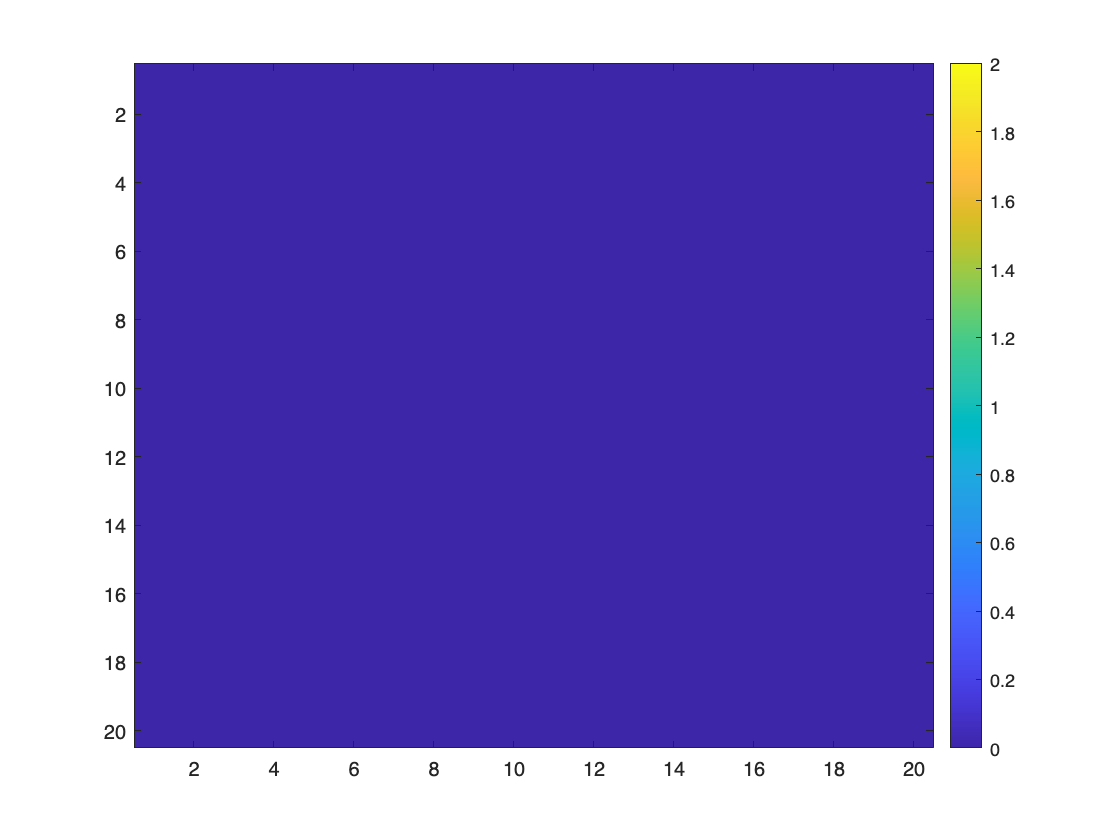

%put your imagesc function here
clims = [0, 2];
imagesc(forestNext,clims)
colorbar

**Task 3:**

Add trees to the simulation, but don't try adding the fire yet (let's take this one step at a time). The idea here is you'll go through each element of the forest and if it's empty, see if a tree should grow or die. If there's already a tree, see if it should die of natural causes. During this process you'll look at the current "forest" matrix, and generate a new "forestNext" matrix.

Setup three nested for loops as described in the ppt slides:

- loop the t variable from 1 to simulationTimeSteps

- loop the i variable from 2 through forestSizeX-1

- loop the j variable from 2 through forestSizeY-1

Notice that you should not loop from 1 to forestSizeX or forestSizeY. Why? The reason is that later on, you will be checking every tree to see if any neighbors are on fire. This is a little trickier if you are at the edge of the forest. So, instead, you can make this easier by setting up the loops to start and end one cell away from the edges.

Now, inside the inner for loop, check the current cell of the forest and check if it's empty. If so, then apply the rules of this simulation to see if a tree should grow. For example, use the rand(1) function to generate a random number. If that random number < treeGrowthRate, then set the corresponding element of forestNext to a tree. 

After the i,j for loops, display the new forest, and then set forest=forestNext. For the imagesc plotting command here, you also need to include "drawnow" so that Matlab redraws the image every time through the loop.

Before running this section of the program, be sure to check each variable assignment statment and make sure there is a ";" at the end, so that the output doesn't get cluttered.

You should see new trees appear as teal-colored squares as time goes on. Depending on the values of treeGrowthRate and simulationTimeSteps, the entire grid may fill up.

%put your code here
% go through each instant in time
for t=1:simulationTimeSteps
    % Go through every location in your forest
    for i=2:forestSizeX-1
        for j=2:forestSizeY-1
            % check forest(i,j), and determine if it’s empty, tree, or fire
            if forest(i, j) == empty
            % based on this decide, if forestNext(i,j) should be set to empty, tree, or fire
                if rand(1)<treeGrowthRate
                    forestNext(i,j) = tree;
                end
            end
        end
    end
    % display the entire forest at this point in time
    imagesc(forestNext,[0 2])
    drawnow;
    forest = forestNext;
end


**Task 4:**

Once you get task 3 working above, it's time to add the fire to the simulation (fireSparkRate) and also for trees to die naturally (treeDeathRate). For now, the fire will not spread; you will implement that later.

Copy your working code from both task 1 and task 3 to the space below. Within the inner for loop, you want to check the current value of forest(i,j) to see if it's empty, a tree, or on fire, and act accordingly. You could do this with a series of "if" statements, or you can use the "switch / case" statements. Look up help on this to see how it works.

- if the current cell is empty: use the rand(1) function to determine if it should grow into a tree (forestNext(i,j)=1).  (You have already done this)

- if the current cell is a tree: use the rand(1) function to determine if it should be set on fire (forestNext(i,j)=2). Also, use the rand(1) function to determine if it should die naturally (forestNext(i.j)=0). 

- if the current cell is on fire, then set it should die (forestNext(i,j)=0).

Once again, before running this section of the program, be sure to check each variable assignment statment and make sure there is a ";" at the end, so that the output doesn't get cluttered.

When you run this, you should see trees (teal) growing and occassionally dying of natural causes or turning into fire (yellow) just before dying.

%copy your working code from tasks 1&3 here

% and make changes as described above
clc;clear;close all;
%initialize variables
forestSizeX = 20;
forestSizeY = 20;
forest = zeros(forestSizeX,forestSizeY);
forestNext = zeros(forestSizeX,forestSizeY);
empty = 0;
tree = 1;
fire = 2;
treeGrowthRate = 0.01;
treeDeathRate = 0.001;
fireSparkRate = 0.001;
simulationTimeSteps = 1000;


% go through each instant in time
for t=1:simulationTimeSteps
    % Go through every location in your forest
    for i=2:forestSizeX-1
        for j=2:forestSizeY-1
            % check forest(i,j), and determine if it’s empty
            if forest(i, j) == empty
                % based on this decide, if forestNext(i,j) should grow a tree
                if rand(1)<treeGrowthRate
                    forestNext(i,j) = tree;
                end

            end
            % check forest(i,j), and determine if it's a tree
            if forest(i,j) == tree
                % based on this decide, if forestNext(i,j) should naturally
                % die
                if rand(1)<treeDeathRate
                    forestNext(i,j) = empty;
                % if tree does not die, check if it should catch on fire
                elseif rand(1)<fireSparkRate
                    forestNext(i,j) = fire;
                end
            end


            % check forest(i,j), and determine if it's on fire
            if forest(i,j) == fire
                forestNext(i,j) = empty;
            end
            
        end
    end
    % display the entire forest at this point in time
    imagesc(forestNext,[0 2])
    drawnow;
    forest = forestNext;
end


**Task 5**

Now it's time for the forest fire to spread! First, let's figure out how to check for neighbors that are on fire. Run the initialization code below to setup a 10x10 test forest that you will use for testing your code. It's mostly an emplty forest, with a few trees and a fire.

%do not change these lines
clc; clear;
forestTest=zeros(6);
forestTest(2,4)=2; %fire
forestTest(3,4)=1; %tree
forestTest(4,4)=1; %tree
forestTest(3,5)=1; %tree
forestTest
i=3; j=4;

Write one line of code to set the variable "neighbors" to include the cells from all neighbors of forestTest(i,j). For the rest of this task, leave off the ";" at the end of each line of code so that you can see if the output is what you expect.

%write one line of code as described above
neighbors = forestTest(i-1:i+1,j-1:j+1);


Write one line of code to set the variable "notEmpty" to true if any of the neighbors are non-zero. The resulting value of notEmpty should be a single logical 1, not a 1x3 logical array. 

%write one line of code as described above
notEmpty = any(neighbors(:) ~= 0);

Write one line of code to set the variable "onFire" to true, if any of the neighbors are on fire (==2). As above, onFire should be a single logical 1, not a 1x3 logical array.

%write one line of code as described above
onFire = any(neighbors(:) == 2);

Now we will eliminate the fire from these neighbors

forestTest(2,4)=0; %empty

Copy your statements above to generate the values of neighbors and onFire and it should reflect that there is no fire among the neighbors. 

%copy code above to generate neighbors
neighbors = forestTest(i-1:i+1,j-1:j+1);
%copy code above to generate onFire
onFire = any(neighbors(:) == 2);


**Task 6**

Now that you know how to check for fire among your neighbors, you can incorporate this into your code. Copy your working code from task 4 to the space below.

In the section where the current cell is a tree, add your code from task 5 to check if a neighbor is on fire. If so, then set this tree on fire. You now have a working forest simulation!

%copy your entire working code from task 4 here
clc;clear;close all;
%initialize variables
forestSizeX = 20;
forestSizeY = 20;
forest = zeros(forestSizeX,forestSizeY);
forestNext = zeros(forestSizeX,forestSizeY);
empty = 0;
tree = 1;
fire = 2;
treeGrowthRate = 0.01;
treeDeathRate = 0.001;
fireSparkRate = 0.001;
simulationTimeSteps = 1000;


% go through each instant in time
for t=1:simulationTimeSteps
    % Go through every location in your forest
    for i=2:forestSizeX-1
        for j=2:forestSizeY-1
            neighbors = forest(i-1:i+1,j-1:j+1); % set array of neighbors
            onFire = any(neighbors(:) == 2); % onFire checks if any neighbors are on fire
            % check forest(i,j), and determine if it’s empty
            if forest(i, j) == empty
                % based on this decide, if forestNext(i,j) should grow a tree
                if rand(1)<treeGrowthRate
                    forestNext(i,j) = tree;
                end

            end
            % check forest(i,j), and determine if it's a tree
            if forest(i,j) == tree
                % check if any of the tree's neighbors are on fire
            
                if onFire
                    forestNext(i,j) = fire;
                % based on this decide, if forestNext(i,j) should naturally
                % die
                elseif rand(1)<treeDeathRate
                    forestNext(i,j) = empty;
                % if tree does not die, check if it should catch on fire
                elseif rand(1)<fireSparkRate
                    forestNext(i,j) = fire;
                end
            end


            % check forest(i,j), and determine if it's on fire
            if forest(i,j) == fire
                forestNext(i,j) = empty;
            end
            
        end
    end
    % display the entire forest at this point in time
    imagesc(forestNext,[0 2])
    drawnow;
    forest = forestNext;
end

% and make changes as described above

**Task 7**

Finally, let's keep track of how many trees are in the forest. Until now, we have looked at a current snapshot of the forest, and determined what the forest will look like at the next moment in time. We have not keep a record of the forest at all moments in time. But now, we would like to keep track of the number of trees throughout the simulation time.

If you run your program as a ".m" script instead of an ".mlx" live script, it will execute faster, so for this last task, create a new script, "forestSimulationTask7_<yourname>.m", and copy your working code from task 6 to this new script. Initialize a new variable "treeCount" with size simulationTimeSteps.

At each iteration of t, determine the number of trees in the forest. At the end of the program, create figure(2) and plot a graph of treeCount vs t. You may want to decrease the value of simulationTimeSteps so that it doesn't take so long before your program reaches the end of the for loop and plots this graph.

**Task 8**

Now, we want you to add something new to the forest. What else could you add to improve the simulation and make it more realistic? Different trees? Fire breaks? Houses? Controlled burns? Do some research to see what might add something valuable to the simulation. Create a new file, "forestSimulationTask8_<yourname>.m" with your solution. 

In the comments at the start of your .m file, describe what you added to the simulation, any rules that govern what you've done, and explain why you chose this.